close all;
clear;
clc;


## Question 2

## Part 1

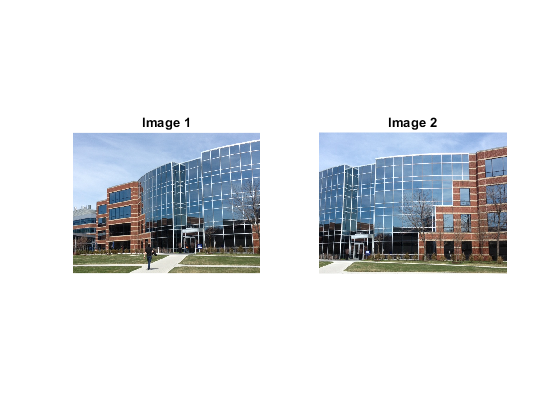

building1 = im2double(imread("building\building1.JPG"));
building2 = im2double(imread("building\building2.JPG"));

figure();
subplot(1,2,1);
imshow(building1, []);
title("Image 1");

subplot(1,2,2);
imshow(building2, []);
title("Image 2");

## Part 2

addpath('sift');

building1_gray = rgb2gray(building1);
building2_gray = rgb2gray(building2);

[frames1,descr1] = sift(building1_gray);
[frames2,descr2] = sift(building2_gray);


## Part 3

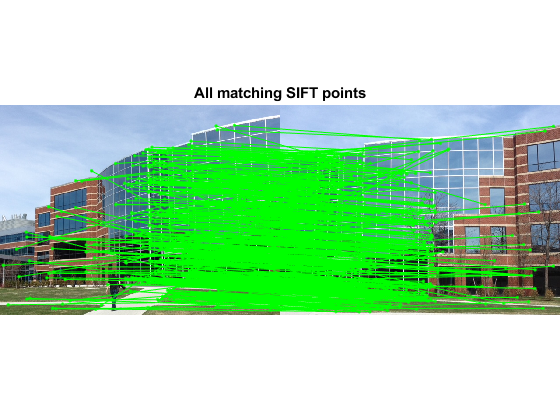


matches = siftmatch(descr1, descr2);
figure();
plotmatches(building1, building2, frames1, frames2, matches);
title('All matching SIFT points');

## Part 4

pts = [[1,2,3,4];[5,6,7,8]]'

pts =      1     5
     2     6
     3     7
     4     8


H = findProjective(pts)

A =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


H =     0.3155   -0.2006    0.2390
   -0.2770    0.3383    0.2444
    0.1161   -0.1698    0.7141


pt = [7,8,1]

pt =      7     8     1


a = H * pt'

a =     0.8430
    1.0116
    0.1686


a ./ a(3)

ans =     5.0000
    6.0000
    1.0000


b =    10.2356    6.3651   -5.3689


ans =    -1.9065   -1.1856    1.0000
